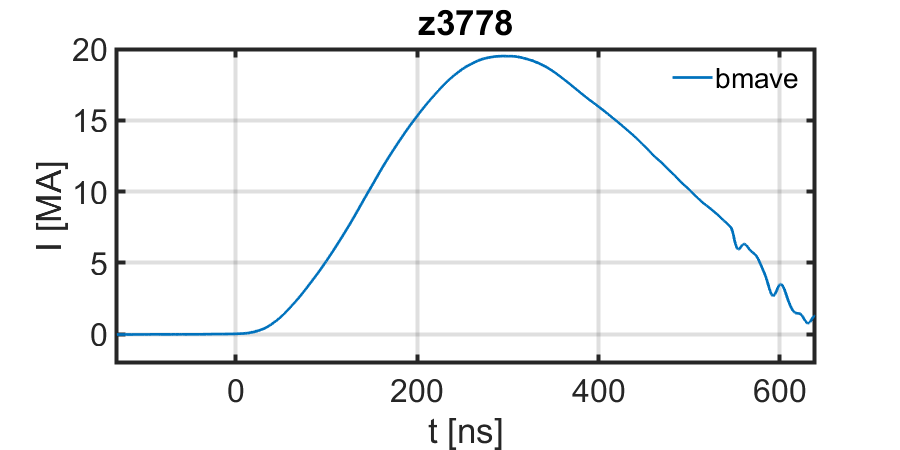

% BCAVE (Average B-Dot Signal)

clc; close all; clear;

shot = 'z3778';

% Plot IDTL signals 

figure

inDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ2_z3778\IDTL signals\');


fname = 'bmave';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V = V - mean(V(idx));

plot(t,V*1.00/1e6,linewidth=2, DisplayName = fname); hold on;

xlabel('t [ns]'); 
ylabel('I [MA]')
title(shot)
grid();
xlim([-100,600])
formatPlots(900,2);

# MARZ3

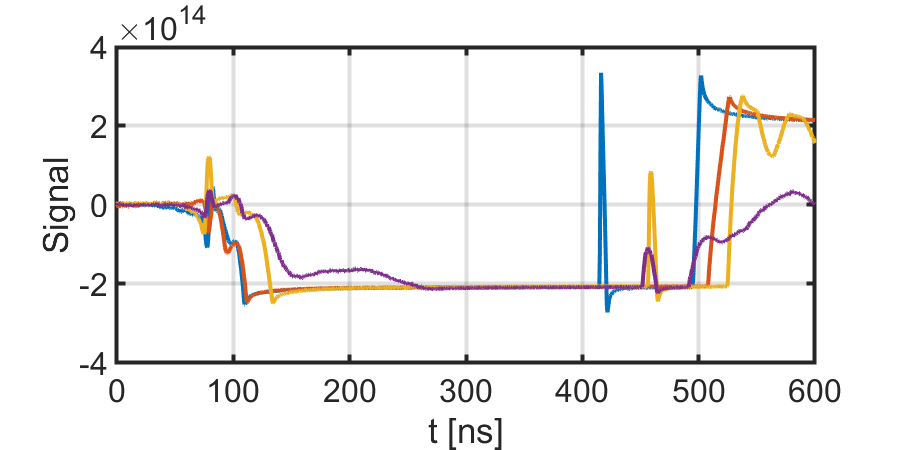

inDir = checkDir('C:\Users\rdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ3_z3781\MITL Bdots\');
dinfo = dir([inDir,'*.txt']);
figure
for ii =1:size(dinfo,1)
data = dlmread([inDir, dinfo(ii).name]);
plot(data(:,1)*1e9-2800,data(:,2),'DisplayName',dinfo(ii).name,"LineWidth",3); hold on;
end
xlim([0,0+600])
xlabel('t [ns]')
ylabel('Signal')
grid();

formatPlots(900,2)
legend('off')

% BCAVE

clc; close all; clear;

shot = 'z3697';

% Plot IDTL signals 

figure

inDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ1_z3697\Waveforms\shot3697_all_waveforms_ASCII\');


fname = 'bm005';
data = dlmread([inDir,fname]);

Error using dlmread (line 62)
The file '\Users\rdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ1_z3697\Waveforms\shot3697_all_waveforms_ASCII\bm0005' could not be opened because: No such file or directory

t = data(:,1)*1e9-2800;
V = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V = V - mean(V(idx));

plot(t,V*1.07/1e6,linewidth=2, DisplayName = fname); hold on;

xlabel('t [ns]'); 
%ylabel('I-dot [MA/ns]')
grid();
xlim([-100,400])
formatPlots(900,2);


# For POP

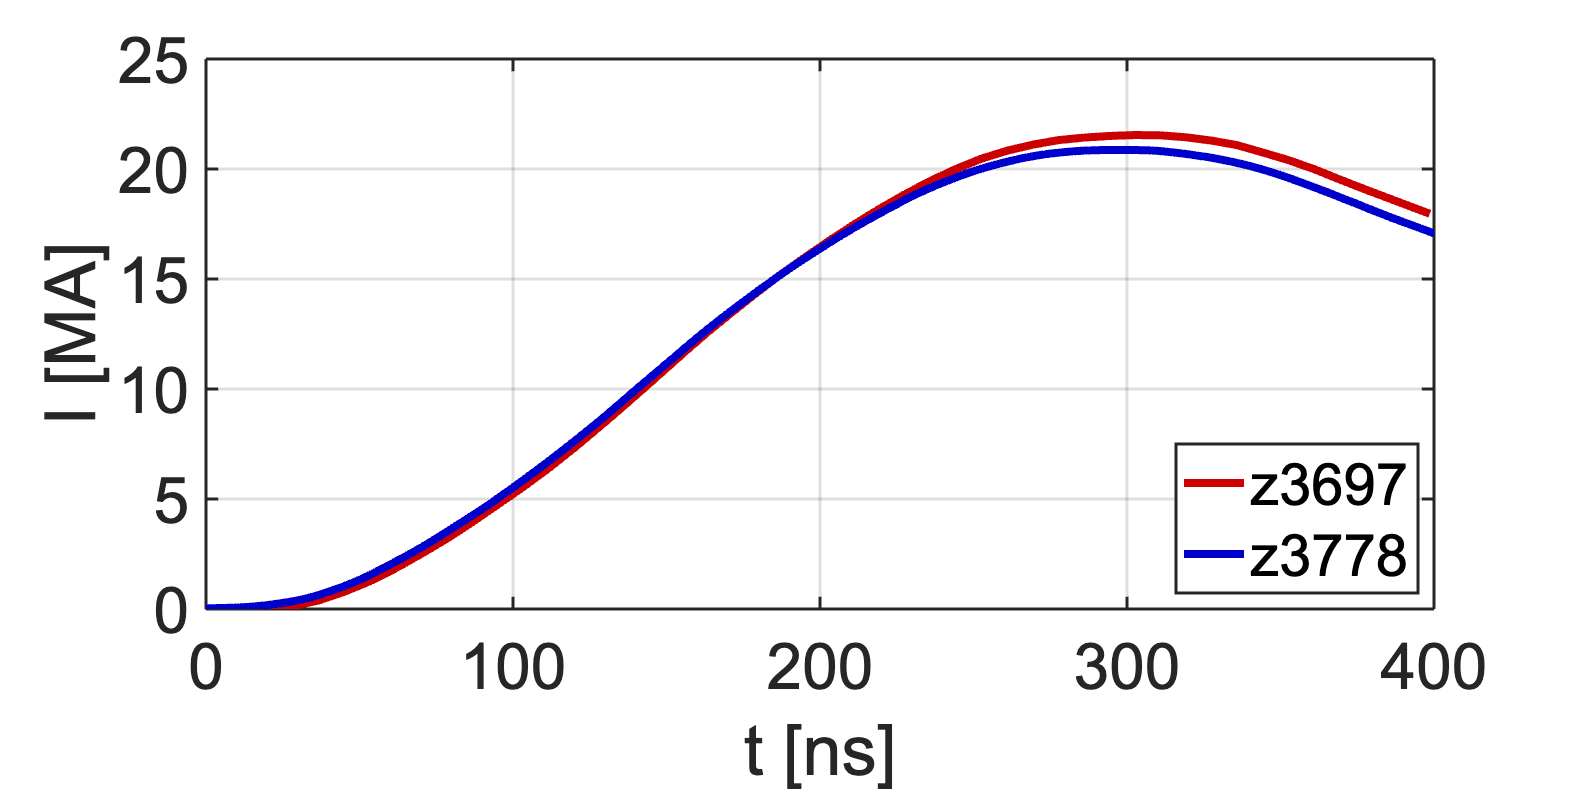

% marz1 - Plot the average B-dot signals showing Current

data = dlmread('z3697_bcave.csv');

figure
plot(data(:,1)-2800,data(:,2)*1.07,LineWidth=4,DisplayName='z3697',color=[0.8 0 0 0.7]);
formatPlots(900,2);
xlabel('t [ns]'); ylabel('I [MA]');
grid();
legend('box','on','location','southeast');

inDir = checkDir('\Users\rdatta\Dropbox (MIT)\PUFFIN group\Data\Z\MARZ\Shots\MARZ2_z3778\IDTL signals\');


fname = 'bmave';
data = dlmread([inDir,fname]);
t = data(:,1)*1e9-2800;
V = data(:,2); % [A/s] (?)
% zero the signal
idx = (t < 0) & (t > -100);
V = V - mean(V(idx));

hold on;
plot(t,V*1.07/1e6,linewidth=4,linestyle='-',DisplayName='z3778',color=[0 0 0.8 0.7]); hold on;
xlim([0,400]); ylim([0,25]);


saveDir = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/Figures_POP/');

% saveas(gcf,[saveDir,'bcave.png']);